# **TD2 Vision assistée par ordinateur**

clc
clear
close all

## 1

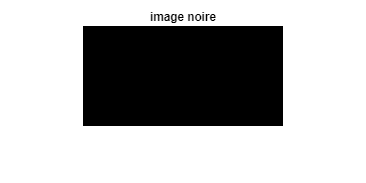

Im1 (1:100,1:200,1) = 0;
Im1 (1:100,1:200,2) = 0;
Im1 (1:100,1:200,3) = 0;

Im1 = uint8(Im1);

imwrite(Im1,'im1.jpg')

figure
imshow(Im1)
title('image noire')

## 2

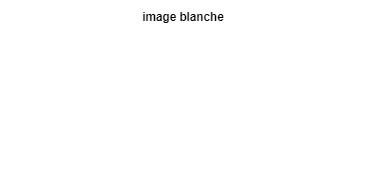

Im2 (1:100,1:200,1) = 255;
Im2 (1:100,1:200,2) = 255;
Im2 (1:100,1:200,3) = 255;

Im2 = uint8(Im2);

imwrite(Im2,'im2.jpg')

figure
imshow(Im2)
title('image blanche')

## 3

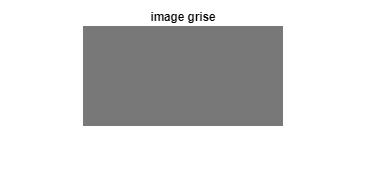

Im3 (1:100,1:200,1) = 120;
Im3 (1:100,1:200,2) = 120;
Im3 (1:100,1:200,3) = 120;

Im3 = uint8(Im3);

imwrite(Im3,'im3.jpg')

figure
imshow(Im3)
title('image grise')

## 4

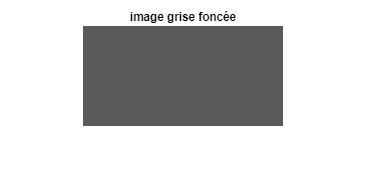

Im4 (1:100,1:200,1) = 90;
Im4 (1:100,1:200,2) = 90;
Im4 (1:100,1:200,3) = 90;

Im4 = uint8(Im4);

imwrite(Im4,'im4.jpg')

figure
imshow(Im4)
title('image grise foncée')

## 5

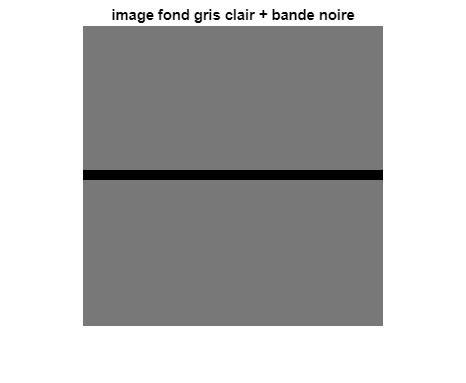

Im5 (1:145,1:300,1) = 120;
Im5 (1:145,1:300,2) = 120;
Im5 (1:145,1:300,3) = 120;

Im5 (145:155,1:300,1) = 0;
Im5 (145:155,1:300,2) = 0;
Im5 (145:155,1:300,3) = 0;

Im5 (155:300,1:300,1) = 120;
Im5 (155:300,1:300,2) = 120;
Im5 (155:300,1:300,3) = 120;

Im5 = uint8(Im5);

imwrite(Im5,'im3.jpg')

figure
imshow(Im5)
title('image fond gris clair + bande noire')

## 6

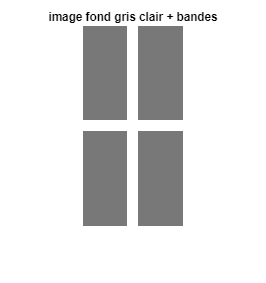

Im6 (1:200,1:100,1) = 120;
Im6 (1:200,1:100,2) = 120;
Im6 (1:200,1:100,3) = 120;

Im6 = uint8(Im6);

Im6 (95:105,:,:) = 255;
Im6 (:,45:55,:) = 255;

imwrite(Im6,'im6.jpg')

figure
imshow(Im6)
title('image fond gris clair + bandes')

## 7

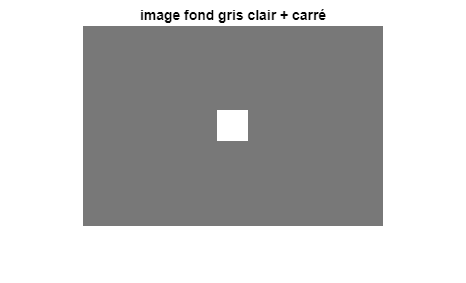

Im7 (1:200,1:300,1) = 120;
Im7 (1:200,1:300,2) = 120;
Im7 (1:200,1:300,3) = 120;

Im7 = uint8(Im7);

Im7 (85:115,135:165,:) = 255;

imwrite(Im7,'im7.jpg')

figure
imshow(Im7)
title('image fond gris clair + carré')

## 8

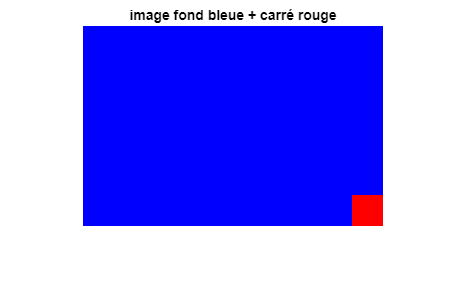

Im8 (1:200,1:300,1) = 0;
Im8 (1:200,1:300,2) = 0;
Im8 (1:200,1:300,3) = 255;

Im8 = uint8(Im8);

m = (170:300);
n = (270:300);

Im8 (170:end,270:end,1) = 255;
Im8 (170:end,270:end,2:3) = 0;

imwrite(Im8,'im8.jpg')

figure
imshow(Im8)
title('image fond bleue + carré rouge')

### **Partie 2**

V = VideoReader('traffic.avi')

V =   VideoReader with properties:

   General Properties:
            Name: 'traffic.avi'
            Path: 'C:\Program Files\MATLAB\R2024a\toolbox\images\imdata'
        Duration: 8
     CurrentTime: 0
       NumFrames: <Calculating...> learn more

   Video Properties:
           Width: 160
          Height: 120
       FrameRate: 15.0000
    BitsPerPixel: 24
     VideoFormat: 'RGB24'



disp(['Il y a ',num2str(V.NumFrames),' images dans la vidéo'])

Il y a 120 images dans la vidéo


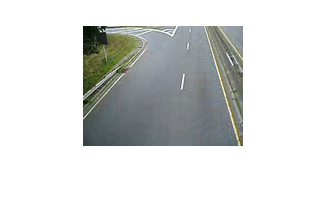

% S1 = readFrame(V); % 1 image
% t1 = V.CurrentTime;
% S2 = readFrame(V);
% imshowpair(S1,S2)
% size(S1)
%f = 1/t1;
%disp(['Il y a ',num2str(f),' images par secondes'])
%disp(['Les images sont de taille :',num2str(V.Height),' x ',num2str(V.Width')])
while hasFrame(V)
    S = readFrame(V);
    imshow(S)
    pause(0.00000001) % trouver la fonction pour attendre
end

**Ecrire un algorithme de detection**

clc
close all
clear

% Essai avec une frame et l'image de référence

V = VideoReader('traffic.avi')

V =   VideoReader with properties:

   General Properties:
            Name: 'traffic.avi'
            Path: 'C:\Program Files\MATLAB\R2024a\toolbox\images\imdata'
        Duration: 8
     CurrentTime: 0
       NumFrames: 120

   Video Properties:
           Width: 160
          Height: 120
       FrameRate: 15.0000
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


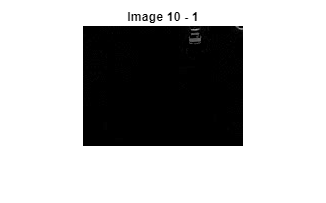

S1 = read(V,1);
S10 = read(V,10);
S1 = rgb2gray(S1);
S10 = rgb2gray(S10);
S1_10 = S10 - S1;
figure
imshow(S1_10)
title('Image 10 - 1')

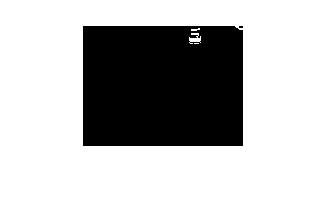

BW = imbinarize(S1_10);
imshow(BW)

nBlack = sum(BW(:));
disp(['il y a ',num2str(nBlack),' pixel pas noirs sur l image'])

il y a 112 pixel pas noirs sur l image


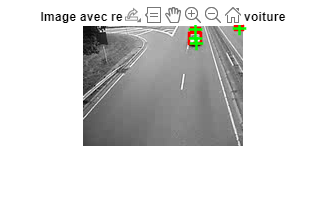


% Trouver les contours de l'objet en mouvement
stats = regionprops(BW, 'BoundingBox', 'Centroid');

% Afficher l'image d'origine avec la voiture
imshow(S10);
hold on;

% Tracer les rectangles autour
for k = 1 : length(stats)
    % Obtenir les coordonnées du rectangle et le centre
    bbox = stats(k).BoundingBox;
    center = stats(k).Centroid;
    
    % Dessiner le rectangle autour de l'objet
    rectangle('Position', bbox, 'EdgeColor', 'r', 'LineWidth', 2);
    
    % Marquer le centre de l'objet
    plot(center(1), center(2), 'g+', 'MarkerSize', 10, 'LineWidth', 2);
    title('Image avec rectangle autour de la voiture')
end

hold off;

On observe que l'on détecte des faux positifs, il faut alors améliorer les paramètres

## **Code sans toolbox**

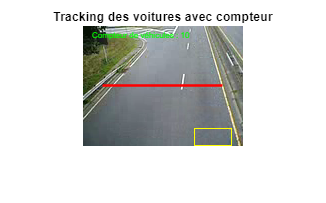

clc;
close all;
clear;

function detectAndTrackVehicles(videoPath)
    % Lire la vidéo
    V = VideoReader(videoPath);
    
    % Lire la première image et convertir en niveau de gris
    frame1 = rgb2gray(readFrame(V));
    
    % Paramètres de détection
    min_area = 100; % Pour éliminer les faux positifs (objets non véhiculaires)
    compteur = 0;  % Initialisation du compteur de véhicules
    
    % Position de la ligne de détection (choisir des coordonnées selon l'image)
    line_y = 60; % Position Y de la ligne
    line_x1 = 20; % Position X de départ
    line_x2 = 140; % Position X de fin
    line_color = 'r'; % Couleur de la ligne (rouge par défaut)
    
    % Boucle pour lire les images
    while hasFrame(V)
        % Lire la prochaine image et convertir en niveau de gris
        frame2 = readFrame(V);
        frame2_g = rgb2gray(frame2);
        
        % Soustraction d'image pour détection de mouvement
        diffImage = abs(double(frame2_g) - double(frame1));
        
        % Seuil pour binariser l'image
        threshold = 20;  
        binaryImage = diffImage > threshold;
        
        % Appliquer un filtre
        binaryImage = conv2(double(binaryImage), ones(3)/9, 'same') > 0.5;
        
        % Détection des régions des véhicules
        regions = detectConnectedRegions(binaryImage, min_area);
        
        % Afficher le frame avec les rectangles de détection
        figure(1)
        imshow(frame2)
        title('Tracking des voitures avec compteur')
        hold on
        
        % Dessiner les rectangles autour des véhicules
        for k = 1:size(regions, 1)
            rectangle('Position', regions(k, :), 'EdgeColor', 'y', 'LineWidth', 0.5);
            
            % Vérifier si le centre du rectangle traverse la ligne
            regionCenterY = regions(k, 2) + regions(k, 4) / 2;
            regionCenterX = regions(k, 1) + regions(k, 3) / 2;
            if regionCenterY > line_y - 5 && regionCenterY < line_y + 5 && ...
               regionCenterX > line_x1 && regionCenterX < line_x2
                compteur = compteur + 1;
                line_color = 'g'; % Changer la ligne en vert lors du comptage
            end
        end
        
        % Dessiner la ligne de détection
        plot([line_x1 line_x2], [line_y line_y], 'Color', line_color, 'LineWidth', 2);
        text(10, 10, ['Compteur de véhicules : ' num2str(compteur)], 'Color', 'g', 'FontSize', 6);
        
        % Réinitialiser la couleur de la ligne
        line_color = 'r';
        
        hold off;
        pause(0.1); % Pause entre les affichages d'images
        
        % Mettre à jour le frame de référence
        frame1 = frame2_g;
    end
end

function regions = detectConnectedRegions(binaryImage, min_area)
    % Fonction pour détecter les régions connectées
    [rows, cols] = size(binaryImage);
    visited = false(rows, cols); % Matrice des pixels déjà détectés
    regions = []; % Stockage des nouvelles régions trouvés
    
    % Boucle pour parcourir chaque pixels de l'image binaire
    for i = 1:rows
        for j = 1:cols
            if binaryImage(i, j) == 1 && ~visited(i, j)
                % Si le pixel est en mouvement et non visité, on démarre un nouveau groupe
                [region, visited] = exploreRegion(binaryImage, visited, i, j);
                
                % Si la région est assez grande
                if size(region, 1) >= min_area
                    % On calcule les limites du rectangle
                    minRow = min(region(:, 1));
                    maxRow = max(region(:, 1));
                    minCol = min(region(:, 2));
                    maxCol = max(region(:, 2));
                    
                    % Ajouter le rectangle à la liste
                    regions = [regions; minCol, minRow, maxCol - minCol, maxRow - minRow];
                end
            end
        end
    end
end

function [region, visited] = exploreRegion(binaryImage, visited, startRow, startCol)
    % Fonction pour explorer une région de pixels connectés
    region = []; % Liste des pixels dans cette région
    stack = [startRow, startCol]; % Initialisation avec le pixel de départ
    [rows, cols] = size(binaryImage);
    
    % Parcours en profondeur pour trouver tous les pixels connectés
    while ~isempty(stack)
        % Récupérer le pixel à traiter
        pixel = stack(end, :);
        stack(end, :) = []; % Retirer le pixel de la pile
        r = pixel(1);
        c = pixel(2);
        
        % Vérifier les limites et si le pixel est déjà visité
        if r >= 1 && r <= rows && c >= 1 && c <= cols && binaryImage(r, c) == 1 && ~visited(r, c)
            % Marquer le pixel comme visité
            visited(r, c) = true;
            % Ajouter le pixel à la région
            region = [region; r, c];
            
            % Ajouter les voisins à la pile (haut, bas, gauche, droite)
            stack = [stack; r-1, c; r+1, c; r, c-1; r, c+1];
        end
    end
end

% Appel de la fonction avec le chemin de la vidéo
detectAndTrackVehicles('traffic.avi');

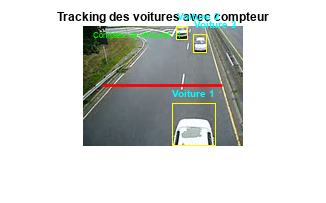

clc;
close all;
clear;

function detectAndTrackVehicles2(videoPath)
    % Lire la vidéo
    V = VideoReader(videoPath);
    
    % Lire la première image et convertir en niveaux de gris
    frame1 = rgb2gray(readFrame(V));
    
    % Paramètres de détection
    min_area2 = 100; % Pour éliminer les faux positifs (objets non véhiculaires)
    compteur2 = 0;  % Initialisation du compteur de véhicules
    
    % Position de la ligne de détection
    line_y2 = 60; % Position Y de la ligne
    line_x1 = 20; % Position X de départ
    line_x2 = 140; % Position X de fin
    line_color2 = 'r'; % Couleur de la ligne (rouge par défaut)
    
    % Structure pour garder les informations des voitures détectées
    vehicleData2 = struct('BoundingBox', {}, 'ID', {}, 'Center', {}, 'Passed', {});
    nextID2 = 1; % ID pour la prochaine voiture détectée
    
    % Boucle pour lire les images
    while hasFrame(V)
        % Lire la prochaine image et convertir en niveaux de gris
        frame2 = readFrame(V);
        frame2_g = rgb2gray(frame2);
        
        % Soustraction d'image pour détection de mouvement
        diffImage2 = abs(double(frame2_g) - double(frame1));
        
        % Seuil pour binariser l'image
        threshold2 = 26;  
        binaryImage2 = diffImage2 > threshold2;
        
        % Filtrage pour lisser le résultat binaire
        binaryImage2 = conv2(double(binaryImage2), ones(3)/9, 'same') > 0.5;
        
        % Détection des régions des véhicules sans toolbox
        regions2 = detectConnectedRegions2(binaryImage2, min_area2);
        
        % Afficher le frame avec les rectangles de détection
        figure(1)
        imshow(frame2)
        title('Tracking des voitures avec compteur')
        hold on
        
        % Mise à jour des données des véhicules détectés
        updatedVehicleData2 = [];
        for k = 1:size(regions2, 1)
            % Obtenir le rectangle et le centre de la région
            bbox2 = regions2(k, :);
            centerX2 = bbox2(1) + bbox2(3) / 2;
            centerY2 = bbox2(2) + bbox2(4) / 2;
            matched2 = false;
            
            % Vérifier si la région correspond à une voiture existante
            for j = 1:length(vehicleData2)
                distance2 = sqrt((centerX2 - vehicleData2(j).Center(1))^2 + ...
                                (centerY2 - vehicleData2(j).Center(2))^2);
                if distance2 < 20
                    % Mise à jour du véhicule existant
                    vehicleData2(j).BoundingBox = bbox2;
                    vehicleData2(j).Center = [centerX2, centerY2];
                    updatedVehicleData2 = [updatedVehicleData2, vehicleData2(j)];
                    matched2 = true;
                    break;
                end
            end
            
            if ~matched2
                % Nouveau véhicule détecté, on assigne un nouvel ID
                newVehicle2.BoundingBox = bbox2;
                newVehicle2.ID = nextID2;
                newVehicle2.Center = [centerX2, centerY2];
                newVehicle2.Passed = false;
                updatedVehicleData2 = [updatedVehicleData2, newVehicle2];
                nextID2 = nextID2 + 1;
            end
        end
        
        % Mettre à jour les informations des véhicules pour la prochaine itération
        vehicleData2 = updatedVehicleData2;
        
        % Dessiner les rectangles autour des véhicules et ajouter des labels
        for j = 1:length(vehicleData2)
            rectangle('Position', vehicleData2(j).BoundingBox, 'EdgeColor', 'y', 'LineWidth', 0.5);
            text(vehicleData2(j).BoundingBox(1), vehicleData2(j).BoundingBox(2) - 10, ...
                sprintf('Voiture %d', vehicleData2(j).ID), 'Color', 'c', 'FontSize', 8, 'FontWeight', 'bold');
            
            % Vérifier si le véhicule a traversé la ligne de détection
            if ~vehicleData2(j).Passed
                regionCenterY2 = vehicleData2(j).Center(2);
                regionCenterX2 = vehicleData2(j).Center(1);
                if regionCenterY2 > line_y2 - 5 && regionCenterY2 < line_y2 + 5 && ...
                   regionCenterX2 > line_x1 && regionCenterX2 < line_x2
                    compteur2 = compteur2 + 1;
                    line_color2 = 'g'; % Changer la ligne en vert lors du comptage
                    vehicleData2(j).Passed = true; % Marquer comme passé
                end
            end
        end
        
        % Dessiner la ligne de détection
        plot([line_x1 line_x2], [line_y2 line_y2], 'Color', line_color2, 'LineWidth', 2);
        text(10, 10, ['Compteur de véhicules : ' num2str(compteur2)], 'Color', 'g', 'FontSize', 6);
        
        % Réinitialiser la couleur de la ligne
        line_color2 = 'r';
        
        hold off;
        pause(0.1); % Pause entre les affichages d'images
        
        % Mettre à jour le frame de référence
        frame1 = frame2_g;
    end
end

function regions2 = detectConnectedRegions2(binaryImage2, min_area2)
    % Fonction pour détecter les régions connectées sans toolbox
    [rows2, cols2] = size(binaryImage2);
    visited2 = false(rows2, cols2); % Matrice des pixels déjà détectés
    regions2 = []; % Stockage des nouvelles régions trouvées
    
    % Boucle pour parcourir chaque pixel de l'image binaire
    for i = 1:rows2
        for j = 1:cols2
            if binaryImage2(i, j) == 1 && ~visited2(i, j)
                % Si le pixel est en mouvement et non visité, on démarre un nouveau groupe
                [region2, visited2] = exploreRegion2(binaryImage2, visited2, i, j);
                
                % Si la région est assez grande
                if size(region2, 1) >= min_area2
                    % On calcule les limites du rectangle
                    minRow2 = min(region2(:, 1));
                    maxRow2 = max(region2(:, 1));
                    minCol2 = min(region2(:, 2));
                    maxCol2 = max(region2(:, 2));
                    
                    % Ajouter le rectangle à la liste
                    regions2 = [regions2; minCol2, minRow2, maxCol2 - minCol2, maxRow2 - minRow2];
                end
            end
        end
    end
end

function [region2, visited2] = exploreRegion2(binaryImage2, visited2, startRow2, startCol2)
    % Fonction pour explorer une région de pixels connectés
    region2 = []; % Liste des pixels dans cette région
    stack2 = [startRow2, startCol2]; % Initialisation avec le pixel de départ
    [rows2, cols2] = size(binaryImage2);
    
    % Parcours en profondeur pour trouver tous les pixels connectés
    while ~isempty(stack2)
        % Récupérer le pixel à traiter
        pixel2 = stack2(end, :);
        stack2(end, :) = []; % Retirer le pixel de la pile
        r2 = pixel2(1);
        c2 = pixel2(2);
        
        % Vérifier les limites et si le pixel est déjà visité
        if r2 >= 1 && r2 <= rows2 && c2 >= 1 && c2 <= cols2 && binaryImage2(r2, c2) == 1 && ~visited2(r2, c2)
            % Marquer le pixel comme visité
            visited2(r2, c2) = true;
            % Ajouter le pixel à la région
            region2 = [region2; r2, c2];
            
            % Ajouter les voisins à la pile (haut, bas, gauche, droite)
            stack2 = [stack2; r2-1, c2; r2+1, c2; r2, c2-1; r2, c2+1];
        end
    end
end

% Appel de la fonction avec le chemin de la vidéo
detectAndTrackVehicles2('traffic.avi');